## データ取り込み

clear, clc, close all
list = dir('*.csv');
numFiles = length(list);
Mx = cell(numFiles,2); % インポート用のセル

## キャリブレーションの平均値取得

% time gaze_X gaze_Y gaze_Z LookAt
Calib = readmatrix(list(1).name);
CalibCell = cell(4,5);
PosStr = ["Center";"Left";"Bottom";"Right";"Top"];
posCol = 11;
for i = 1:size(PosStr,1)
    % ターゲットを見ている間のデータを抽出
    CalibCell{i,1} = Calib(Calib(:,posCol)==(i-1),:);
    for k = 2:4
        CalibCell{i,k} = mean(CalibCell{i,1}(:,k));
%         CalibCell{i,k} = std(CalibCell{i,1}(:,k));
    end
    CalibCell{i,5} = PosStr(i,1);
end

descStr = ["data" "x_mean" "x_std" "y_mean" ...
    "y_std" "z_mean" "z_std" "Position"]

descStr = 1×8 の string 配列
    "data"    "x_mean"    "x_std"    "y_mean"    "y_std"    "z_mean"    "z_std"    "Position"


for i = 1:size(descStr,1)
    CalibCell{size(PosStr,1)+1,i} = descStr(i,1);
end
% 点数を統一する処理が必要。点数の真ん中から100点とる？


## 実験データの取得・整理

% 実験条件の名前
condName = ["Vision_come";"Haptic_come";"Vis_Hap_come";"None_come";
            "Vision_trans";"Haptic_trans";"Vis_Hap_trans";"None_trans";
            ];
noteNumCol = 6;
condCol = 4; % データ内に条件が記載された列
distCol = 5; % 発砲時の距離を記録した列
elaspCol = 3; % 発砲時の距離を記録した列
findCol = 8; % ターゲット視界内=true, 視界外=false
eventCol = 7; % 0: miss, 1: success: 2: spawn
for i = 2:numFiles
    tmpCell = readcell(list(i).name);
    idx = find(condName == tmpCell{2,condCol});
    Mx{idx,1} = readmatrix(list(i).name);

    % 特徴行の抽出
    tArr = Mx{idx,1};
    succIdx = find(and(tArr(:,eventCol)==1,...
        tArr(:,noteNumCol)>4)); % 成功時の行
    failIdx = find(and(tArr(:,eventCol)==0, ...
        tArr(:,noteNumCol)>4)); % 失敗時の行
    endIdx = sort([succIdx; failIdx]);% 成功＋失敗の行

    beginIdx = find(and(tArr(:,eventCol)==2,...
        tArr(:,noteNumCol)==5)); % 実験開始行
    finishIdx = size(tArr,1);

    % 結果が0/1の試行をカウント
    Mx{idx,2} = size(find(tArr(:,eventCol) == 0),1);
    % 結果が1の場合（距離）
    Mx{idx,3} = size(succIdx,1);
    Mx{idx,4} = mean(tArr(succIdx,distCol));
    % 試行

    % 経過時間（成功のみ）
    Mx{idx,5} = mean(tArr(succIdx,elaspCol));

    % 発見までの時間（成功のみ）
    rotX = 12;
    % 頭部の回転角の総量を計算
    rotAmt = [0 0 0];
    ansDist=zeros(4,1); % 到着時のdistを記録する配列
    for k = beginIdx : finishIdx - 1
        for ax = 0:2
            c = rotX + ax;
            tmpRot = abs(cos(deg2rad(tArr(k+1,c)))) ...
                - abs(cos(deg2rad(tArr(k,c))));
            rotAmt(1,ax+1) = rotAmt(1,ax+1) + abs(tmpRot);
        end
    end
    Mx{idx,6} = rotAmt(1,1);
    Mx{idx,7} = rotAmt(1,2);
    Mx{idx,8} = rotAmt(1,3);
    Mx{idx,9} = sum(rotAmt);
    % 説明追記
    Mx{idx,10} = condName(idx,1);

end
descStr = ["data";"Fail";"Succeed";"dist";"clearTime";
           "rotX";"rotY";"rotZ";"rotSum";"Condition"];
for i = 1:size(descStr,1)
    Mx{size(condName,1)+1,i} = descStr(i,1);
end


## 視線グラフ化

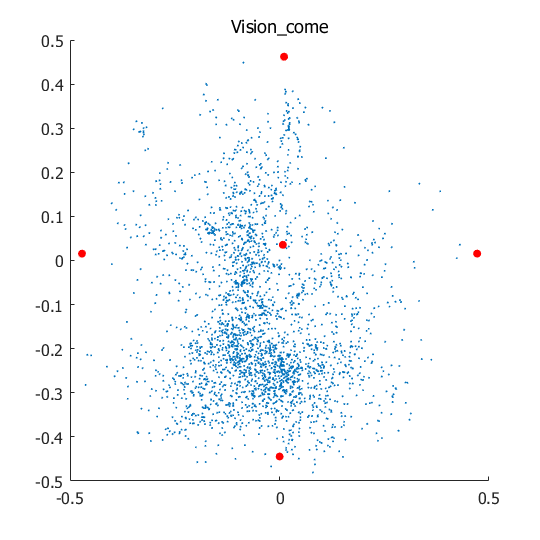

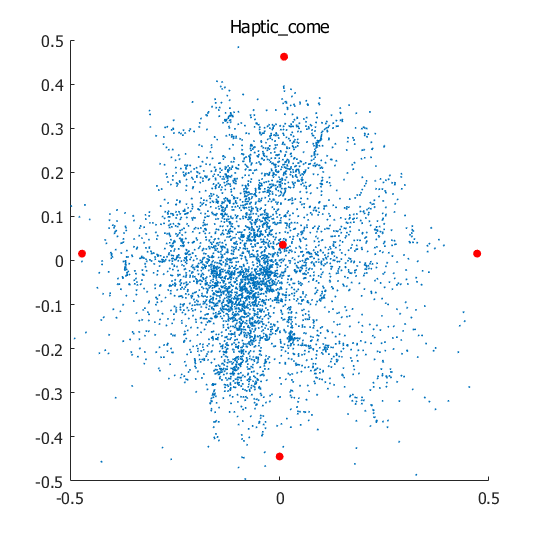

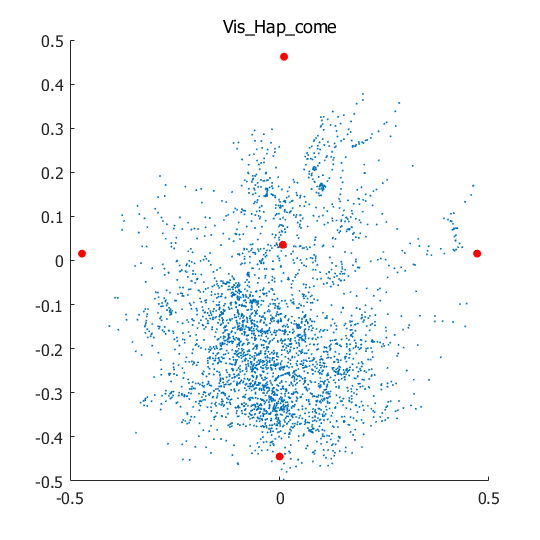

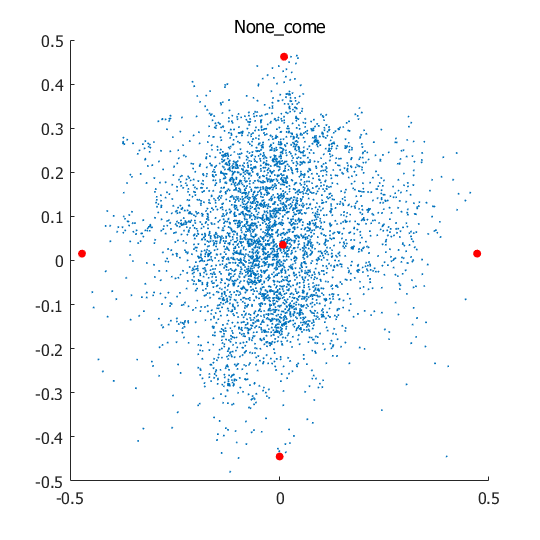

% time gaze_X_Y_Z camRot_X_Y_Z camPos_X_Y_Z	condition
close all;
% for i = 1:size(condName,1)
for i = 1:4
    condNum = i;
    gaze = Mx{condNum,1}(:,9:10);
    x = gaze(:,1);
    y = gaze(:,2);

    %    視線散布図追加
    figure('Position',[0 0 540 540])
    hold on
    scatter(x,y,'SizeData',1);
    %     キャリブレーション結果の追加
    xx = [CalibCell{:,2}];
    yy = [CalibCell{:,3}];
    scatter(xx, yy,'filled','r');
    title(condName(condNum,1),'interpreter','none');
    limRange = 0.5;
    xlim([-limRange,limRange]);
    ylim([-limRange,limRange]);
    set(gcf, 'visible', 'on')
    ax = gca; % current axes
    ax.FontSize = 12;
    ax.FontName = 'tahoma';

    hold off
    saveas(gcf,strcat('scatter',condName(condNum,1),'.png'));

%     %     時系列データ込み3次元プロット
%     figure('Position',[0 -700 540 540])
%     plot3(t,x,y);
%     set(gcf, 'visible', 'on')
%     title(condName(condNum,1),'interpreter','none');
end